# Spectres

## Accès dossier et choix essai

Il est nécessaire d'avoir lancé "Correlation.mat" précédement

clear;
Type = "C6C0SN";
Materiau = "3135";
Eprouvette ='1';
Numero = '3';
 
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);
load(strcat(Naming,'.mat'));
%WF = TimeT(WF);
WF(end,:) = [];
chNbre = Nch(HDD);

## Etude des spectres des différents capteurs

% Calcul des spectres moyens de chaque ch
lg = ["Pico" "Nano30" "Nano30" "µ80" "µ200" "R50"];
tiledlayout(height(chNbre)/2,2);


SPmoy = zeros(2*height(WF),height(chNbre));
for c = 1:length(chNbre)
    for i = 1:chNbre(c)
        [sp,freq] = pspectrum(WF.(strcat(string(c),'_',string(i))),WF.Time);
        SPmoy(:,c) = SPmoy(:,c)+sp;
    end
    SPmoy(:,c) = SPmoy(:,c)/chNbre(c);
    nexttile
    semilogx(freq,db(SPmoy(:,c),"power"));
    xlim([8*10e3 10e5]);
    legend(lg(c));
    title(strcat("Spectre moyen du capteur ",string(c)," de l'essai C6C0SN 3"));
end

Unrecognized table variable name 'Time'.


figure();
plot(freq,db(SPmoy,"power"));
title(strcat("Spectres moyens superposés, essai C6C0SN 3"));

## Etude "remplissage" WF 

res = zeros(width(WF),1);
res = zeros(width(WF),1);
for i = 1:width(WF)
    a = find(WF{:,i}~=0);
    res(i) = max(a);
end
% res contient le nombre de valeurs différentes de 0 parmis les 10
% dernieres valeurs de chaque WF.
% non0 = find(res~=0)
Longueur_moyennes_WF = mean(res)

Longueur_moyennes_WF = 393.0708

Nbre_WF_depassant_1800 = find(res>=1800)

Nbre_WF_depassant_1800 =           11
          18
         282
        2903
        3882


## Re-echantillonnage

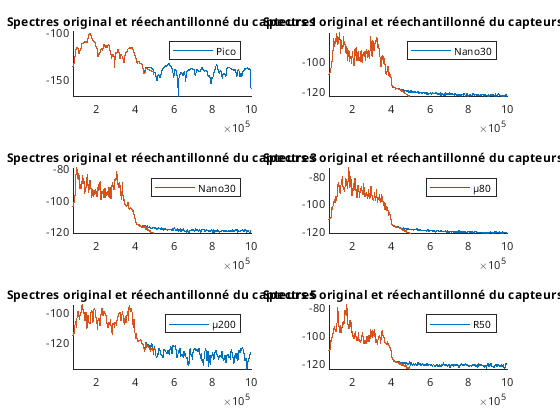

WFr = resample(WF.("1_1"),2,1);
% Calcul des spectres moyens de chaque ch
lg = ["Pico" "Nano30" "Nano30" "µ80" "µ200" "R50"];
tiledlayout(height(chNbre)/2,2);

SPmoy = zeros(2*height(WF),height(chNbre));
SPmoyR = zeros(2*height(WF),height(chNbre));
for c = 1:length(chNbre)
    for i = 1:chNbre(c)
        Wr = resample(WF.(strcat(string(c),'_',string(i))),1,2);
        Wr = timetable(Wr,'RowTimes',WF.Time(1:2:end));
        [sp,freqR] = pspectrum(Wr);
        SPmoyR(:,c) = SPmoyR(:,c)+sp;
        [sp,freq] = pspectrum(WF.(strcat(string(c),'_',string(i))),WF.Time);
        SPmoy(:,c) = SPmoy(:,c)+sp;
    end
    nexttile
    hold on
    SPmoyR(:,c) = SPmoyR(:,c)/chNbre(c);
    SPmoy(:,c) = SPmoy(:,c)/chNbre(c);
    semilogx(freq,db(SPmoy(:,c),"power"));
    semilogx(freqR,db(SPmoyR(:,c),"power"));
    hold off
    xlim([8*10e3 10e5]);
    legend(lg(c));
    title(strcat("Spectres original et réechantillonné du capteurs ",string(c)));
end

% moy = 0;
% moytot = 0;
% l = size(WF);
% for i=1:l(2)
%     X = WF{:,i};
%     Y = [X zeros(l(1),1)];
% %     X = lowpass(X,1e6,Fs);
%     moytot = moytot+fft(X);
%     moy = moy+fft(Y(1:2:end)); 
% end
% moytot = moytot/l(2);
% moy = moy/(2*l(2));
% % lim = 2.5;
% figure();
% Fs = -1/(1000000*(WF.Temps(1)-WF.Temps(2))); % Freq d'échantillonage en Hz
% Te = 1/Fs;
% N = l(1);
% freq = [0:N-1]/(N*Te);
% stem(freq/Te,abs(moytot));%stem est un type de plot souvent utilisé pour représenter les spectres
% xlabel('Fréquence en MHz');
% ylabel('Composantes de Fourier (normalisées)');
% xlim([0 lim]);
% figure();
% Fs = -1/(1000000*(WF.Temps(1)-WF.Temps(3))); % Freq d'échantillonage en Hz
% Te = 1/Fs;
% N = fix(l(1));
% freq = [0:N-1]/(N*Te);
% stem(freq/Te,abs(moy));
% xlabel('Fréquence en MHz');
% ylabel('Composantes de Fourier (normalisées)');
% xlim([0 lim/2.5]);
% 
% 
% figure();
% Fs = -1/(1000000*(WF.Temps(1)-WF.Temps(2))); % Freq d'échantillonage en Hz
% Te = 1/Fs;
% N = l(1);
% freq = [0:N-1]/(N*Te);
% plot(freq/Te,20*log10(moytot));%stem est un type de plot souvent utilisé pour représenter les spectres
% xlabel('Fréquence en MHz');
% ylabel('Composantes de Fourier (normalisées)');
% xlim([0 lim]);
% figure();
% Fs = -1/(1000000*(WF.Temps(1)-WF.Temps(3))); % Freq d'échantillonage en Hz
% Te = 1/Fs;
% N = fix(l(1));
% freq = [0:N-1]/(N*Te);
% plot(freq/Te,20*log10(moy));%stem est un type de plot souvent utilisé pour représenter les spectres
% xlabel('Fréquence en MHz');
% ylabel('Composantes de Fourier (normalisées)');
% xlim([0 lim/2.5]);